# Simulate a neuron based on the AdEx model

Reference: Naud et. al., (2008) *Biol Cybern*, 99: 335-347.

See also [http://www.scholarpedia.org/article/Adaptive_exponential_integrate-and-fire_model](http://www.scholarpedia.org/article/Adaptive_exponential_integrate-and-fire_model) 

The AdEx model is governed by only three equations. 


$$C\frac{dV}{dt} = -g_L(V-E_L) + g_L\Delta_T \exp\left(\frac{V-V_T}{\Delta_T}\right) + I - w$$



$$\tau_w\frac{dw}{dt} = a(V-E_L)-w$$



$$\text{if }V>0 \text{ then } \begin{cases} V=V_r \\ w=w+b \end{cases}$$


This model can, however, produce a large diversity of neural behaviors, according to parameter settings.

We will translate these equations into MATLAB code, run the simulation, and record the membrane potential.

## Model parameters here

% stimulation environment parameters
simDur = 500; % simulation time in ms
dt     = .01; % discretization in ms

% vector of time points
timevec = (0:simDur/dt)*dt;

% time-varying input current
Iinput = zeros(size(timevec));
Iinput = 500; % pA

% model parameters for figure 4d
C      = 200; % Capacitance
gl     =  10; % leak conductance
El     = -58; % leak voltage
vt     = -50; % resting membrane potential
delT   =   2; % spike Width Factor
a      =   2; % resonator/integrator variable
tauW   = 120; % adaptation decay time
b      = 100; % adaptation jump (update for w)
vreset = -46; % voltage reset

## Simulation


% vector to store membrane potential
membPoten = [vt; zeros(simDur/dt,1)];
v = vt;
w = 0;
vpeak = 0; % spike threshold


% simulation in loop over time
for timei = 1:length(timevec)-1
    
    % set input for this time point
    Iin = 
    
    % integration
    v = 
    % note: update w by pre-updated v
    w = 
    
    
    % update and store variables
    if v>=vpeak
        
    else
        % no AP, just store v
        membPoten(timei+1) = v;
    end
end

## Visualize the membrane potential over time

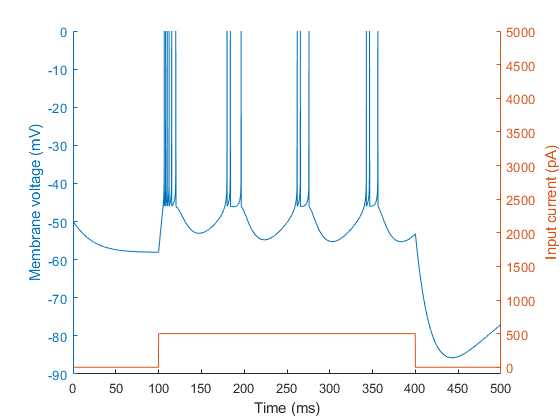

% generate the plot
yyaxis left
plot()

% visualize the input
plot(timevec,Iinput)
set(gca,'ylim',[-100 5000])
ylabel('Input current (pA)')

box off
xlabel('Time (ms)')